clear;
clc;
port_name      = "COM4";
baud           = 115200;
num_words_all  = 256;
num_mel        = 32;

s = serialport(port_name, baud, "Timeout", 10);
flush(s);

start_code = uint8([hex2dec('03') hex2dec('CC') hex2dec('AA') hex2dec('55')]);
stop_code  = uint8([hex2dec('CC') hex2dec('03') hex2dec('55') hex2dec('AA')]);

disp("Waiting for MEL frame...");

Waiting for MEL frame...


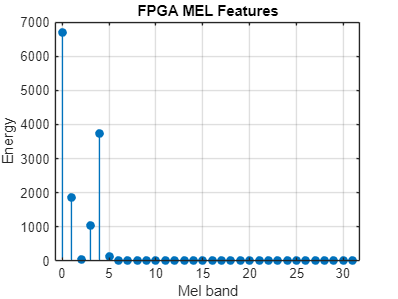


buf = zeros(1,4096,'uint8');
idx = 0;

got_start = false;

while true
    b = read(s,1,"uint8");
    if isempty(b)
        error("Timeout");
    end

    idx = idx + 1;
    buf(idx) = b;

    if idx >= 4 && ~got_start
        if isequal(buf(idx-3:idx), start_code)
            got_start = true;
            idx = 0;
        end
    elseif got_start && idx >= 4
        if isequal(buf(idx-3:idx), stop_code)
            payload = buf(1:idx-4);
            break;
        end
    end
end

need_bytes = num_words_all*4;
if numel(payload) < need_bytes
    warning("Payload short: %d bytes", numel(payload));
    payload = [payload zeros(1,need_bytes-numel(payload),'uint8')];
else
    payload = payload(1:need_bytes);
end

mel_all = zeros(num_words_all,1,"uint32");
for k = 1:num_words_all
    b = payload(4*k-3:4*k);
    mel_all(k) = uint32(b(1)) ...
               + bitshift(uint32(b(2)),8) ...
               + bitshift(uint32(b(3)),16) ...
               + bitshift(uint32(b(4)),24);
end

clear s;

mel_fpga = mel_all(1:num_mel);

figure;
stem(0:num_mel-1, double(mel_fpga), 'filled');
title("FPGA MEL Features");
xlabel("Mel band");
ylabel("Energy");
grid on;